## **0. Initialization**

clc;
clear;
img_org = imread("charact2.bmp");%read the original image

## 1. Display the original image

figure("Name","the original image");

imshow(img_org);
img_gray = rgb2gray(img_org);           % transform to gray image
imshow(img_gray);
save('img_gray.mat','img_gray');

## 2. Implement 3x3 averaging mask and rotating mask.Try masks in other sizes

### 2.1 Apply 3x3 averaging mask on the original image

load('img_gray');
figure("Name","3x3 averaging mask image");
average_mask_3by3 = ones(3,3)./9;                           % create the mask
img_3X3average = imfilter(img_gray,average_mask_3by3);     % apply the mask

imshow(img_3X3average);                                    % display the 3x3 averaged image
montage([img_gray, img_3X3average]);                       % compair with origin grey image

There are not many differents. In the filtered image, the colors are lighter and the image is blurrier

The results of different 3X3 convolusion kernel shows below

montage([  img_gray,  img_3X3average; ...
           imfilter(img_gray,([1 1 1; 1 2 1; 1 1 1]./10)), ...
           imfilter(img_gray,([1 2 1; 2 4 2; 1 2 1]./16))])

We also tried different size of filter, noticed that larger mask results more blurry

montage([   img_gray,                          img_3X3average; ...
            imfilter(img_gray,ones(5,5)./25),   imfilter(img_gray,ones(10,10)./100)]);

中值滤波器

montage([img_gray, medfilt2(img_gray)])

高斯滤波器

montage([img_gray, imgaussfilt(img_gray,2)])
plot(imhist(img_3X3average));
save('3X3average.mat', "img_3X3average");

### 2.2 Apply 3x3 rotating mask on the original image

load('img_gray.mat');

img_3X3rotate = img_gray;
img_size = size(img_gray);
height = img_size(1);
width = img_size(2);

tic
for i = 3: height-2
    for j = 3: width-2

        min_dispersion = inf;
        min_mean = inf;

        for k = -1:1
            for l = -1:1
                % 提取mask
                sub_matrix = img_gray(i+k-1:i+k+1, j+l-1:j+l+1);
                
                % 计算mask内所有像素的平均灰度
                mean_intensity = mean2(sub_matrix);

                % 计算mask内所有像素的标准差（方差的开根号，可以代替用于比较方差大小）
                dispersion = std2(sub_matrix);

                if (dispersion < min_dispersion)
                    min_dispersion = dispersion;
                    min_mean = mean_intensity;
                end
            end
        end
        
        % 取值为方差最小的mask的灰度均值
        img_3X3rotate(i,j) = min_mean;

    end
end
toc

Elapsed time is 35.598490 seconds.


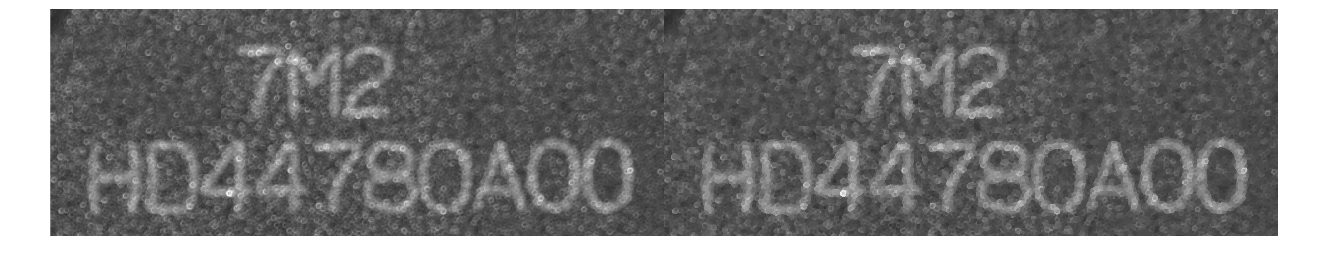

montage([img_gray, img_3X3rotate])

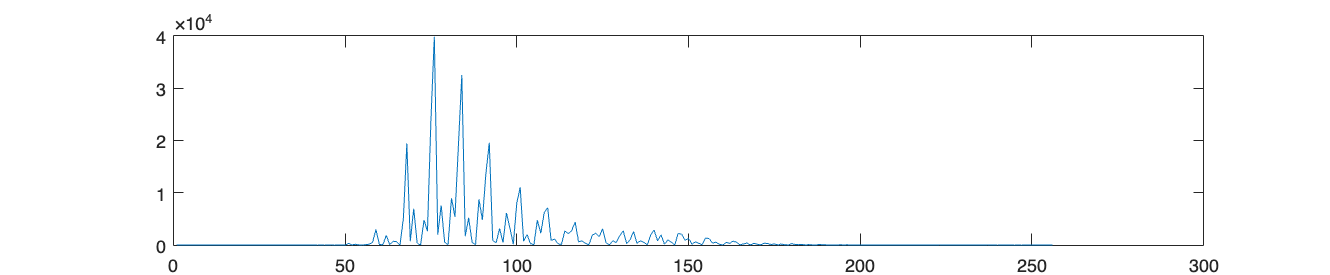

plot(imhist(img_gray));

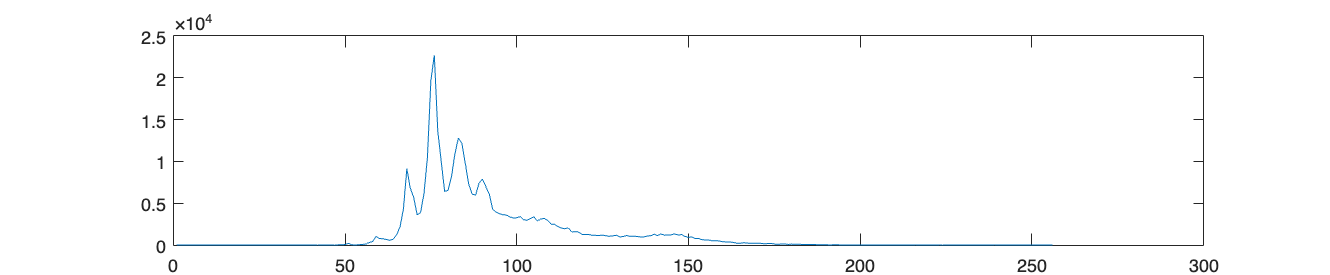

plot(imhist(img_3X3rotate));

save('3X3rotate.mat', "img_3X3rotate");

#### 2.2.1 Improve the speed of rotating mask.

load('img_gray.mat');

img_3X3rotate = img_gray;
img_size = size(img_gray);
height = img_size(1);
width = img_size(2);

mean_matrix = zeros(height,width);
dispersion_matrix = zeros(height,width);

tic
for i = 2: height-1
    for j = 2: width-1
        sub_matrix = img_gray(i-1:i+1,j-1:j+1);
        mean_matrix(i,j) = mean2(sub_matrix);
        dispersion_matrix(i,j) = std2(sub_matrix);
    end
end

for i = 3: height-2
    for j = 3: width-2

        min_dispersion = dispersion_matrix(i,j);
        min_mean = mean_matrix(i,j);

        for k = -1:1
            for l = -1:1
                dispersion = dispersion_matrix(i+k,j+l);
                if (dispersion < min_dispersion)
                    min_dispersion = dispersion;
                    min_mean = mean_matrix(i+k,j+l);
                end
            end
        end
       
        img_3X3rotate(i,j) = min_mean;
    end
end
toc

Elapsed time is 3.987509 seconds.


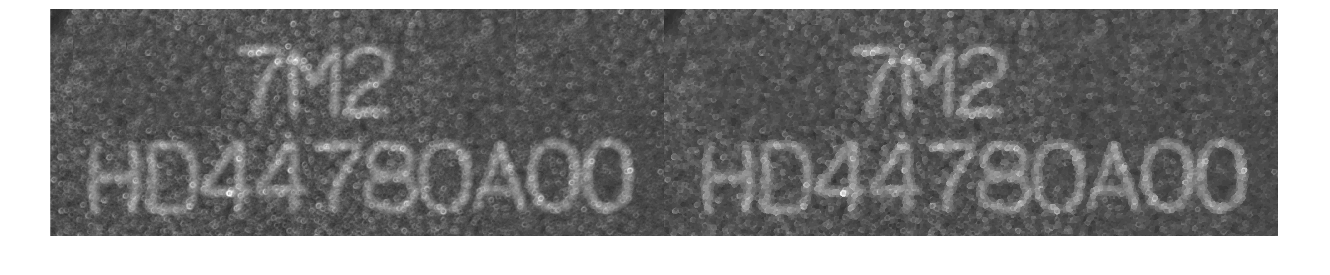

montage([img_gray, img_3X3rotate])

plot(imhist(img_gray));

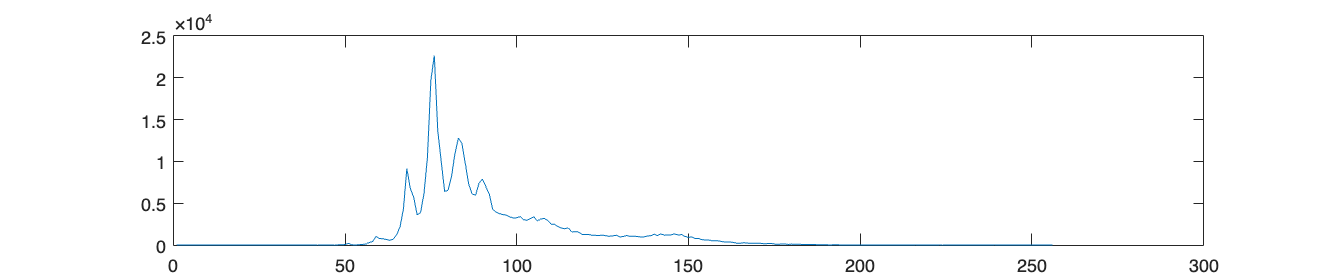

plot(imhist(img_3X3rotate));

save('3X3rotate.mat', "img_3X3rotate");

load("3X3rotate.mat");
load("3X3average.mat");
load("img_gray.mat");

tiledlayout(1,3);
nexttile
plot(imhist(img_gray));
title("original gray")
nexttile
plot(imhist(img_3X3average));
title("3X3 average")
nexttile
plot(imhist(img_3X3rotate));
title("3X3 rotate")

## 3. Create an image which is a sub-image of the original image comprising the middle  line – HD44780A00.

load('img_gray.mat')

figure("Name","Cropped sub image - HD4478A00");
img_hd = imcrop(img_gray,[1 184 990 367]); %Crop a sub-image
imshow(img_hd);
imshow(wiener2(img_hd,[10 10]))

## 4. Create a binary image from Step 3 using thresholding.

load("3X3rotate.mat");
load("3X3average.mat");
load("img_gray.mat");

% create a gray level histogram first
tiledlayout(1,3);
nexttile
plot(imhist(imcrop(img_gray,[1 184 990 367])));
title("original gray")
nexttile
plot(imhist(imcrop(img_3X3average,[1 184 990 367])));
title("3X3 average")
nexttile
plot(imhist(imcrop(img_3X3rotate,[1 184 990 367])));
title("3X3 rotate")     

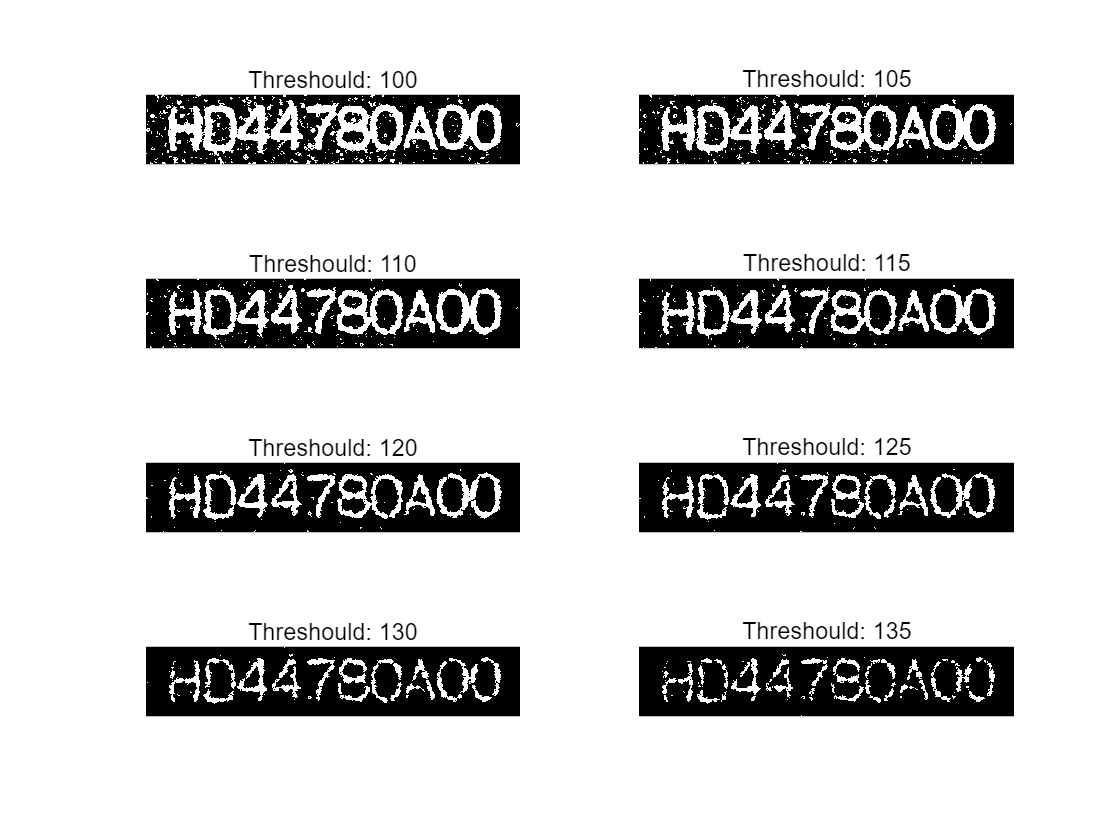

clf
load("3X3average.mat");
img_hd_filtered = imcrop(img_3X3average,[1 184 990 367]);

figure;
for i = 1:8
    threshold = 100 + (i-1)*5;
    subplot(4, 2, i);
    
    % 显示图像
    imshow(imbinarize(img_hd_filtered,threshold/255));
    
    % 添加标题
    title(sprintf('Threshould: %d', threshold));
end

clf
% thresgold the image
img_threshold = imbinarize(img_hd_filtered,115/255); %apply thresholding


使用连通区域分割来处理连通区域

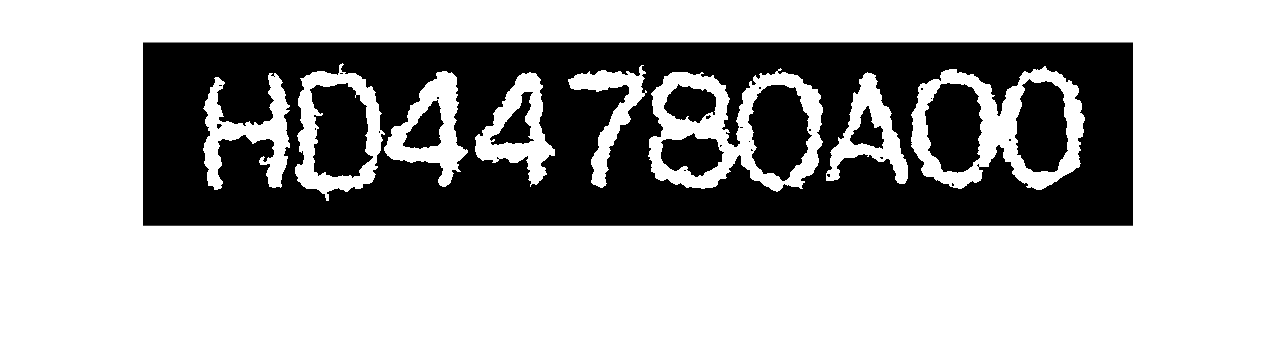

CC = bwconncomp(img_threshold);

% 计算每个连通分量的面积
stats = regionprops(CC, 'Area');

% 获取面积数组
area = [stats.Area];

% 定义阈值
threshold = 500;

% 过滤掉小于阈值的连通区域
img_threshold = bwareaopen(img_threshold, threshold);

% 显示过滤后的图像
imshow(img_threshold);

save('binary_image.mat', "img_threshold")

## 5. Determine the outline(s) of characters in the image.

使用Sobel算子来提取边缘

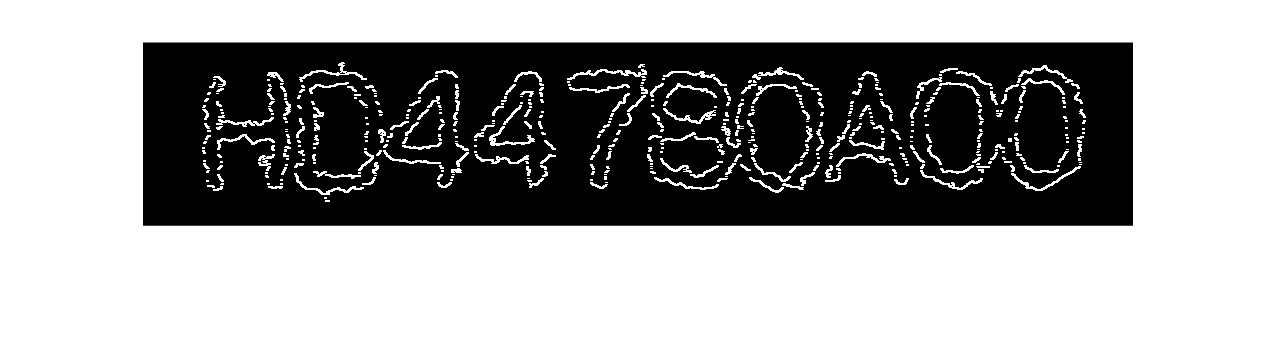

load('binary_image.mat')
% Gradient in X direction
G_x_filter = [  -1  -2  -1;
                0   0   0;
                1   2   1];
G_x = imfilter(img_threshold,G_x_filter);
G_x_minus = imfilter(img_threshold,-G_x_filter);
imshow(G_x + G_x_minus);

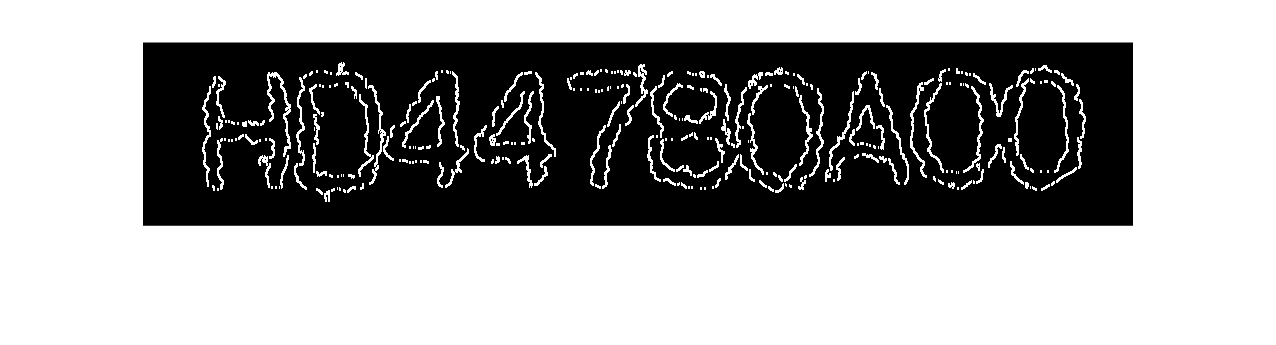

% Gradient in Y direction
G_y_filter = [  -1  0   1;
                -2  0   2;
                -1  0   1];
G_y = imfilter(img_threshold,G_y_filter);
G_y_minus = imfilter(img_threshold,-G_y_filter);
imshow(G_y+G_y_minus);

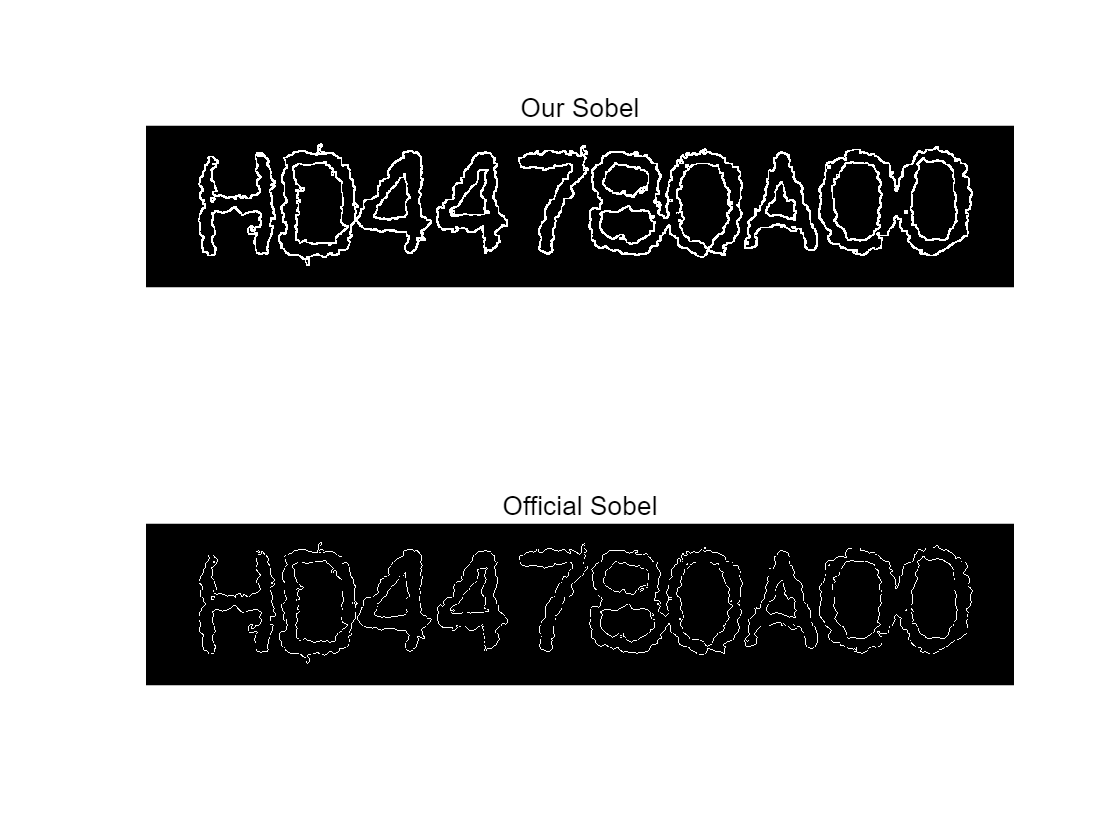

figure;
subplot(2, 1, 1);
imshow(G_x+G_y+G_x_minus+G_y_minus);        % Our Sobel
title('Our Sobel');
subplot(2, 1, 2);
imshow(edge(img_threshold,"sobel"));        % Official Sobel
title('Official Sobel');

## 6. Segment the image to separate and label the different characters

Label and segment image regions with "8-neighborhood" connectivity.

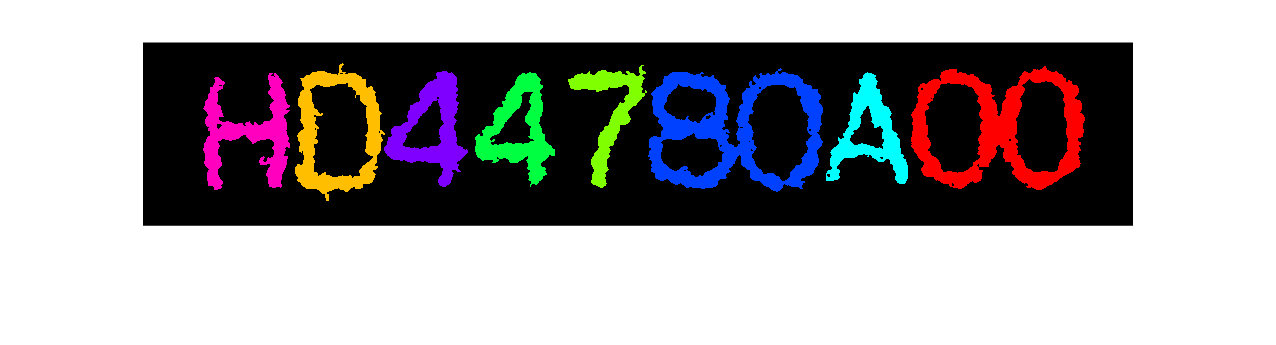

load('binary_image.mat')
clf
% Segmentation
labeledImage = bwlabel(img_threshold, 8); % 8-Neighborhood Region Labelling
labelProps = regionprops(logical(labeledImage), 'BoundingBox', 'Area'); % Bounding Box for each Region

% Mark the different region with color
coloredLabels = label2rgb(labeledImage, 'hsv', 'k', 'shuffle');
imshow(coloredLabels);

Noise Reduction is done before the segmentation.

clf
% Noise Reduction for small white area
img_denoise = img_threshold;
minArea = 300; % Area threshold value for elimination

for i = 1:numel(labelProps)
    if labelProps(i).Area < minArea
        noise = ceil(labelProps(i).BoundingBox);
        img_denoise(noise(2):(noise(2)+noise(4)-1), noise(1):(noise(1)+noise(3)-1)) = 0; 
    end
end

% Re-Segmentation
labeledImage = bwlabel(img_denoise, 8);
labelProps = regionprops(logical(labeledImage), 'BoundingBox', 'Area');

% Show the image after Noise Reduction and display the bounding box
coloredLabels = label2rgb(labeledImage, 'hsv', 'k', 'shuffle');
imshow(coloredLabels);

Try to further segment the character if they are connected together by width threshold.

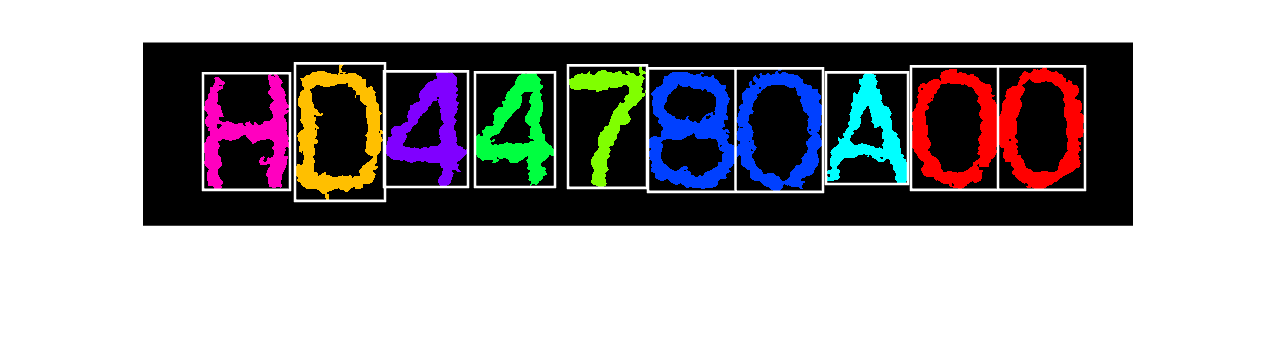

hold on;
threshold = 100; % Set your threshold here

newBoundingBoxes = [];
newCharacters = {};

boundingBoxes = cat(1, labelProps.BoundingBox);
for i = 1:size(boundingBoxes, 1)
    if boundingBoxes(i,3) > threshold % If the width of the bounding box is greater than the threshold
        % Split the image into two along the width
        newBoundingBoxes(end+1,:) = [boundingBoxes(i,1), boundingBoxes(i,2), boundingBoxes(i,3)/2, boundingBoxes(i,4)];
        newBoundingBoxes(end+1,:) = [boundingBoxes(i,1) + boundingBoxes(i,3)/2, boundingBoxes(i,2), boundingBoxes(i,3)/2, boundingBoxes(i,4)];
        character1 = imcrop(labeledImage, newBoundingBoxes(end-1,:));
        character2 = imcrop(labeledImage, newBoundingBoxes(end,:));
        newCharacters{end+1} = character1;
        newCharacters{end+1} = character2;
    else
        newBoundingBoxes(end+1,:) = boundingBoxes(i,:);
        character = imcrop(labeledImage, newBoundingBoxes(end,:));
        newCharacters{end+1} = character;
    end
end

for i = 1:size(newBoundingBoxes, 1)
    rectangle('Position', newBoundingBoxes(i,:), 'EdgeColor', 'w', 'LineWidth', 1);
end
hold off;

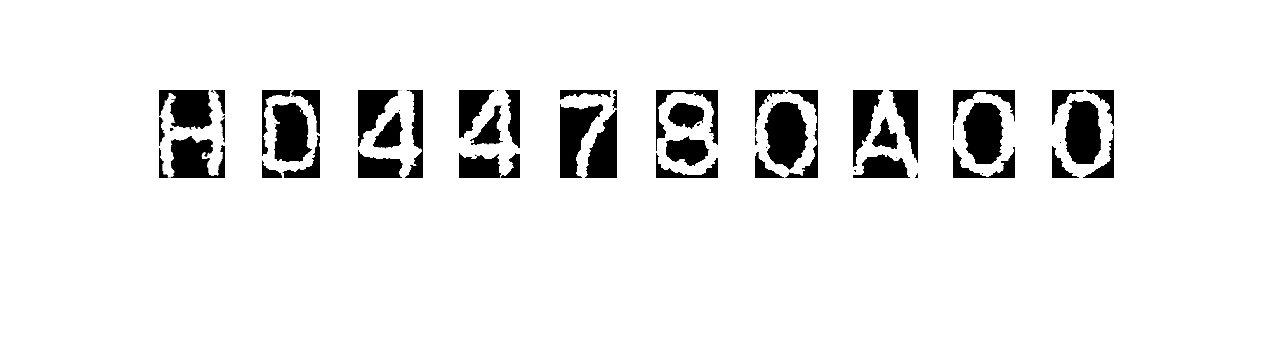

characters = cell(size(boundingBoxes, 1), 1);

for i = 1:size(newBoundingBoxes, 1)
    montage(newCharacters, 'Size', [1, length(newCharacters)], 'BorderSize', [80 40],'BackgroundColor','w');
    hold on;
end
hold off;

The seperate character will be saved into file respectively. Additionally, resizing of the image can be tuned here.

% Store Character
character_folder = 'character';
rmdir(character_folder,'s');
mkdir(character_folder);

% Resize the image, for ratio tunning in Problem #8
resize_ratio = 0.92;

for i = 1:10
    characterFileName = sprintf('character_%02d.png', i);
    black_background = zeros(128);
    resized_character = imresize(newCharacters{i}, resize_ratio);

    row_start = floor((size(black_background, 1) - size(resized_character, 1)) / 2) + 1;
    col_start = floor((size(black_background, 2) - size(resized_character, 2)) / 2) + 1;

    black_background(row_start:(row_start + size(resized_character, 1) - 1), ...
        col_start:(col_start + size(resized_character, 2) - 1), :) = resized_character;
    image1_resized = uint8(~ black_background(1:128,1:128))*255;
    imwrite(image1_resized, fullfile(character_folder, characterFileName));
end

## 7. Classification of Image

### 7.1 Design a CNN to classify each characters

First, import the dataset here.

dataset_folder = 'dataset';
imds = imageDatastore(dataset_folder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Split the dataset into training set and validation set
[imdsTrain, imdsTest] = splitEachLabel(imds, 0.75, 'randomized');

Set a multilayer CNN network configuration.

layers = [
    imageInputLayer([128,128,1])
    
    convolution2dLayer(3,8,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,8,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,16,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,32,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)

    convolution2dLayer(3,64,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,128,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    convolution2dLayer(3,256,"Padding","same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,"Stride",2)
    
    dropoutLayer

    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];

options = trainingOptions("adam","InitialLearnRate",0.001,"MaxEpochs",11,"Shuffle","every-epoch", ...
    "ValidationData",imdsTest,"ValidationFrequency",20,"MiniBatchSize",64,"Verbose",false, ...
    "ExecutionEnvironment","auto","Plots","training-progress");

Then, train the dataset and do the test.

net = trainNetwork(imdsTrain,layers,options);
save('CNN.mat', "net");
load('CNN.mat');
MLPPred = classify(net,imdsTest);
accuracy = sum(MLPPred == imdsTest.Labels)/numel(imdsTest.Labels);
fprintf('[TEST SET] Accuracy: %.2f%%.',100*accuracy);

Use this network to classify the character in the given image.

% Label the character with the truth
validation = imageDatastore(character_folder, 'IncludeSubfolders', true);
validation.Labels = categorical(["H","D","4","4","7","8","0","A","0","0"]);

% Classify the character use CNN network
validation_pred = classify(net,validation);

for i = 1:10
    I = readimage(validation, i);
    True_Label = validation.Labels(i);
    Pred_Label = validation_pred(i);
    subplot(2, 5, i);
    imshow(I);
    if True_Label == Pred_Label
        color = [0.2 0.8 0.2];
    else
        color = [1 0 0];
    end
    title({['True: ' char(True_Label)], ['Pred: ' char(Pred_Label)]},'FontSize', 11,'Color', color);
end
% Calculate the accuracy
validation_accuracy = sum(validation_pred == validation.Labels)/numel(validation.Labels);
fprintf('[CLASSIFICATION] Accuracy: %.2f%%.',100*validation_accuracy);

### 7.2**: Design another model (MLP) to classify each characters in Image 1**

mlplayers = [
    imageInputLayer([128 128 1]) % Input layer (adjust dimensions based on your images)

    fullyConnectedLayer(102)    % 1st hidden layer with 100 neurons
    reluLayer                   % Activation function (Rectified Linear Unit)

    fullyConnectedLayer(56)     % 2nd hidden layer with 50 neurons
    reluLayer

    fullyConnectedLayer(28)     % 3rd hidden layer with 25 neurons
    reluLayer

    fullyConnectedLayer(14)     % 4rd hidden layer with 25 neurons
    reluLayer

    fullyConnectedLayer(7) % Output layer (numClasses represents number of classes)
    softmaxLayer                % Softmax for classification
    classificationLayer];       % Classification layer

options = trainingOptions("adam","InitialLearnRate",0.001,"MaxEpochs",9,"Shuffle","every-epoch", ...
    "ValidationData",imdsTest,"ValidationFrequency",20,"MiniBatchSize",64,"Verbose",false, ...
    "ExecutionEnvironment","auto","Plots","training-progress");
% Train the network
mlpnet = trainNetwork(imdsTrain, mlplayers, options);

% Evaluate the model on the test set

MLPPred = classify(mlpnet,imdsTest);
accuracy = sum(MLPPred == imdsTest.Labels)/numel(imdsTest.Labels);
fprintf('[TEST SET] Accuracy: %.2f%%.',100*accuracy);

YTestPred = classify(mlpnet, validation);
accuracy = sum(YTestPred == validation.Labels) / numel(YTestPred); % Calculate accuracy
for i = 1:10
    I = readimage(validation, i);
    True_Label = validation.Labels(i);
    Pred_Label = YTestPred(i);
    subplot(2, 5, i);
    imshow(I);
    if True_Label == Pred_Label
        color = [0.2 0.8 0.2];
    else
        color = [1 0 0];
    end
    title({['True: ' char(True_Label)], ['Pred: ' char(Pred_Label)]},'FontSize', 11,'Color', color);
end
fprintf('[CLASSIFICATION] Accuracy: %.2f%%.',100*accuracy);